**Normalisation of data**

clc

data=readtable("AverageLift.csv","ReadVariableNames",0);
data=table2array(data)

data =    20.0000         0   20.0000    0.6600
   20.0000         0   50.0000    0.5660
   20.0000  100.0000   20.0000    1.0073
   20.0000  100.0000   50.0000    0.8639
  200.0000         0   20.0000    0.7093
  200.0000         0   50.0000    0.6375
  200.0000  100.0000   20.0000    1.1048
  200.0000  100.0000   50.0000    0.9233
   20.0000   50.0000   35.0000    0.7662
  200.0000   50.0000   35.0000    0.8378


table_heads=['Re','Overlap','AOA','COL']

table_heads = 'ReOverlapAOACOL'

x=data(:,1:3);
y=data(:,4);

x1_min=min(x(:,1))

x1_min = 20

x1_max=max(x(:,1))

x1_max = 200

x2_min=min(x(:,2))

x2_min = 0

x2_max=max(x(:,2))

x2_max = 100

x3_min=min(x(:,3))

x3_min = 20

x3_max=max(x(:,3))

x3_max = 50


x_norm=[];
for i=1:width(x)
    temp=x(:,i);
    temp=(temp-min(temp))/(max(temp)-min(temp));
    x_norm=[x_norm,temp];
end
x_norm

x_norm =          0         0         0
         0         0    1.0000
         0    1.0000         0
         0    1.0000    1.0000
    1.0000         0         0
    1.0000         0    1.0000
    1.0000    1.0000         0
    1.0000    1.0000    1.0000
         0    0.5000    0.5000
    1.0000    0.5000    0.5000



x_train=x_norm(1:30,:);
y_train=y(1:30,:);

x_test=x_norm(31:end,:);
y_test=y(31:end,:);


[f1_m, f2_m, f3_m]=meshgrid(0:0.05:1,0:0.05:1,0:0.05:1);

f1=reshape(f1_m,[],1);
f2=reshape(f2_m,[],1);
f3=reshape(f3_m,[],1);
size(f1_m)

ans =     21    21    21


x_temp=[];
for i=0:0.05:1
    for j=0:0.05:1
        for k=0:0.05:1
            x_temp=[x_temp;i,j,k];
        end
    end
end




**Bayesian Optimisation **

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |  0.00071698 |    0.065944 |  0.00071698 |  0.00071698 |     0.011047 |
|    2 | Best   |  0.00039862 |    0.083246 |  0.00039862 |  0.00055771 |   0.00014331 |
|    3 | Accept |   0.0014309 |    0.050563 |  0.00039862 |  0.00084875 |      0.09208 |
|    4 | Accept |    0.016444 |    0.078802 |  0.00039862 |   0.0031404 |      0.57961 |
|    5 | Accept |  0.00039862 |    0.091658 |  0.00039862 |  0.00039886 |   0.00014362 |
|    6 | Accept |   0.0009185 |    0.062645 |  0.00039862 |   0.0003987 |     0.022332 |
|    7 | Accept |  0.00039862 |    0.069839 |  0.00039862 |   0.0003979 |   0.00076572 |
|    8 | Best   |  0.

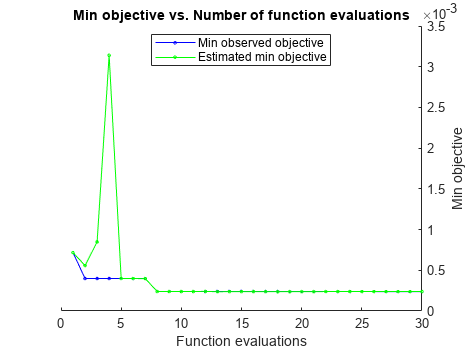

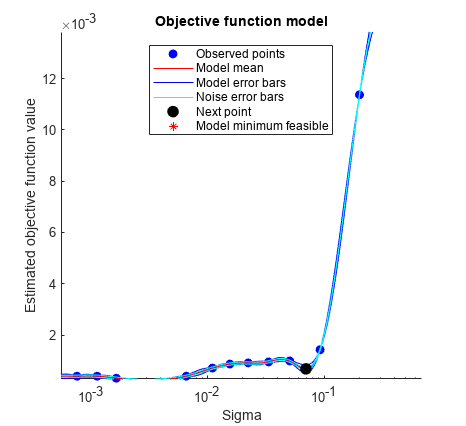


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 11.7434 seconds
Total objective function evaluation time: 1.8418

Best observed feasible point:
      Sigma  
    _________

    0.0028449

Observed objective function value = 0.00023847
Estimated objective function value = 0.00023838
Function evaluation time = 0.046768

Best estimated feasible point (according to models):
      Sigma  
    _________

    0.0032114

Estimated objective function value = 0.00023881
Estimated function evaluation time = 0.055902



%n=input("Number of iteration for bayesian optimisation: ");

rng default
model = fitrgp(x_train,y_train,'KernelFunction','squaredexponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));


model

model =   RegressionGP
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 30
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                       KernelFunction: 'SquaredExponential'
                    KernelInformation: [1×1 struct]
                        BasisFunction: 'Constant'
                                 Beta: 0.8834
                                Sigma: 0.0032
                    PredictorLocation: []
                       PredictorScale: []
                                Alpha: [30×1 double]
                     ActiveSetVectors: [30×3 double]
                        PredictMethod: 'Exact'
                        ActiveSetSize: 30
                            FitMethod: 'Exact'
                      ActiveSetMethod: 'Random'
                    IsActiveSetVector: [30×1 logical]
           

x_test1 =          0         0         0
         0         0    0.0500
         0         0    0.1000
         0         0    0.1500
         0         0    0.2000
         0         0    0.2500
         0         0    0.3000
         0         0    0.3500
         0         0    0.4000
         0         0    0.4500


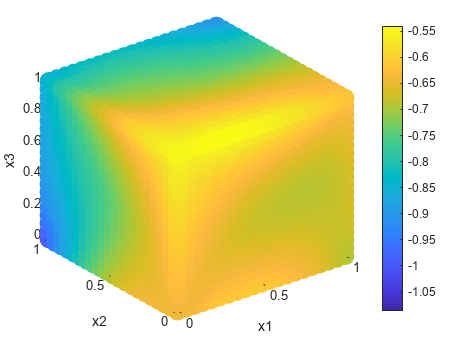

GlobalSearch stopped because it analyzed all the trial points.

All 12 local solver runs converged with a positive local solver exit flag.


l_opt =     0.2346    0.0000    1.0000


Error percent is: 4.869987e-01


Error percent is: 4.869987e-01

lambda=[10];

losses=[];

loss_test=0;
for j=lambda
    for i=1:5
        model=fitrgp(x_train,y_train);
        acquisiton=@(l)(-1*(-1*predict(model, [l(1),l(2),l(3)])+j*Out2(@predict,model,[l(1),l(2),l(3)])));
        
        y_temp=[];
        for i=1:length(x_temp)
            temp=x_temp(i,:);
            y_temp=[y_temp;-1*acquisiton(temp)];
        end
        
        x_test1=x_temp
        
        figure 
        s=scatter3(x_test1(:,1),x_test1(:,2),x_test1(:,3),200,y_temp,"filled");
        xlabel("x1");
        ylabel("x2");
        zlabel("x3");
        colorbar

        lb = [0,0,0];
        ub = [1,1,1];
        x0=[0,0,0];
        gs = GlobalSearch;


        problem = createOptimProblem('fmincon','x0',x0,'ub',ub,'lb',lb,'objective',acquisiton);
        l_opt=run(gs,problem)
        x1=(l_opt(1))*(x1_max-x1_min)+x1_min;
        x2=(l_opt(2))*(x2_max-x2_min)+x2_min;
        x3=(l_opt(3))*(x3_max-x3_min)+x3_min;
        x_train=[x_train;l_opt];
        temp=input("Value of y at "+string(x1)+" , "+string(x2)+" , "+string(x3)+" : ");
        y_train=[y_train;temp];
        loss_test=Loss_grp(model,x_test,y_test)*100;

        if (loss_test<=0.5)
            fprintf("Error percent is: %d",loss_test);
            break
        end
    end
    losses=[losses,loss_test];
    fprintf("\nError percent is: %d",loss_test);
end

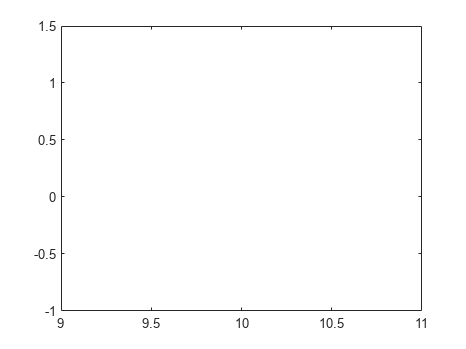


plot(lambda,losses,"Color","red");

**Plotting the final Function**

y_temp=[];

for i=1:length(x_temp)
    temp=x_temp(i,:);
    y_temp=[y_temp;predict(model,temp)];
end

y_new=[];
for i=1:length(f1)
    temp=[f1(i),f2(i),f3(i)];
    y_new=[y_new;predict(model,temp)];
end

y_new=reshape(y_new,size(f1_m));
y_new;
T=array2table([f1,f2,f3,reshape(y_new,[],1)]);
writetable(T, 'plotting_data.csv', 'WriteVariableNames', true)

k=0:0.05:1;
x_test=x_temp

x_test =          0         0         0
         0         0    0.0500
         0         0    0.1000
         0         0    0.1500
         0         0    0.2000
         0         0    0.2500
         0         0    0.3000
         0         0    0.3500
         0         0    0.4000
         0         0    0.4500


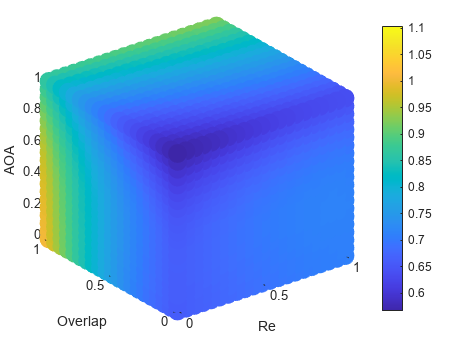

s=scatter3(x_test(:,1),x_test(:,2),x_test(:,3),200,y_temp,"filled","o");
xlabel("Re");
ylabel("Overlap");
zlabel("AOA");
colorbar

function Z = Out2(FUN,varargin)
[~,Z] = FUN(varargin{:});
end
